# Distribution of star ratings on File Exchange

This Live Script plots the distribution of all star ratings made on File Exchange.

## Query the database

connection = database( ...
    'fileexchange', ...
    'fileexchange', ...
    'fileexchange', ...
    'com.mysql.jdbc.Driver', ...
    'jdbc:mysql://cmtyreport:13306/' ...
);

query = 'SELECT rating, COUNT(rating) FROM feedbacks WHERE visible IS TRUE AND rating > 0 GROUP BY rating ORDER BY rating DESC';

result = fetch(connection, query);

rows = cell2mat(result);

## Plot the results

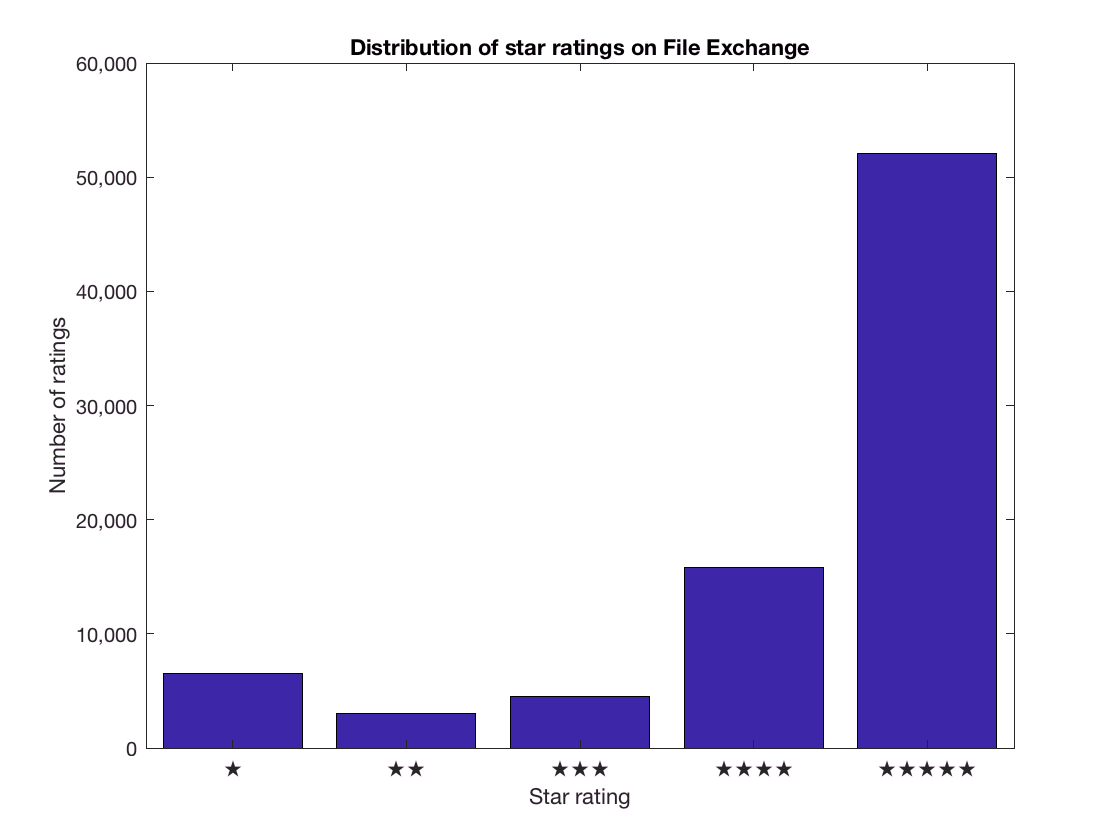

bar(rows(:,1), rows(:,2))

title('Distribution of star ratings on File Exchange');
xlabel('Star rating');
ylabel('Number of ratings');

axes = gca;
axes.YAxis.Exponent = 0;
axes.YAxis.TickLabelFormat = '%,i';
axes.XAxis.TickLabels = {'★', '★★', '★★★', '★★★★', '★★★★★'};

## Clean up after ourselves

close(connection);